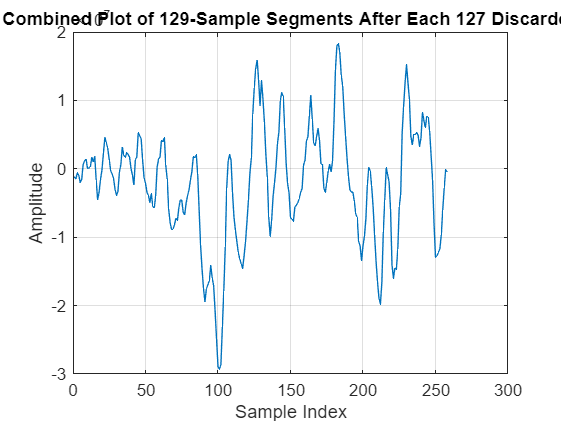

clear; clc;


% Step 1: Generate 128-point Hann window in floating point
N = 128;
hann_win = hann(N);  % Column vector, values in [0, 1)

% Step 2: Convert to Q15 format (int16 scaled by 32767)
scale_factor = 32767;
hann_q15 = int16(round(hann_win * scale_factor));  % Round to nearest integer

% Step 3: Display as a comma-separated vector (for HDL or C code)
fprintf('Hann window in Q15 format (int16):\n');
disp(hann_q15');

% Step 4: (Optional) Save to file
fileID = fopen('hann_q15.txt', 'w');
fprintf(fileID, '%d,\n', hann_q15);
fclose(fileID);

fprintf('Q15 Hann window saved to hann_q15.txt\n');
